# Zernike polynomial calculations

Zernike polynomials can be expressed (referenced) using two indices, 

- one representing the highest order of the radial polynomial term (n), and 

- the other representing the frequency of the azimuthal sinusoid (m). (See wiki for more details.)

The polynomials can also be represented in a single-indexing scheme (j) using OSA standards, which is easier to manage in vector form for Matlab. We use that method here.  There are ISETCam functions to translate between labeling methods (wvfOSAIndexToName, wvfOSAToVectorIndex,wvfOSAToZernikeNM).

Each radial order has (order+1) number of polynomial terms (and therefore, order+1 number of Zernike coefficients to represent them). Thus, 0th order has 1 term, 1st order has 2 terms, etc.

In this tutorial we will be working with up to 10 orders of Zernike polynomials. Counted out, this represents 1+2+3+...+11 = 66 terms for radial orders 0 through 10. The 0th order term (piston) doesn't affect the PSF and we will leave it at 0. 

Additionally, the 1st order terms (coeffs 1 and 2, known as tip and tilt) only serve to shift the PSF along the x or y axis. They show up in the plots of this tutorial

See also:

  t_wvfOverview.mlx

## Initialize plotting parameters

ieInit;

The tutorial only uses 1 wavelength, although the code typically specifies multiple wavelengths. For plotting in this tutorial, we use these parameters. 

waveIdx = 1;
maxMM = 2;       % For plotting
maxUM = 20;      % For plotting.
pupilfuncrangeMM = 5;  % For plotting

## Diffraction limited PSF

The diffraction limited wavefront  has the 0's for all Zernike coeffs. Notice that the calcpupilMM is by default 3, meaning we are simulating the wavefront PSF for a pupil of 3MM diameter.  This code dumps out the structure so you can get a sense of what is in it.

The validation script v_wvfDiffractionPSF compares the diffraction limited PSFs obtained in this manner with those obtained by computing an Airy disk and shows that they match.

wvf0 = wvfCreate;
wvfPrint(wvf0);


Wavefront structure name is default

Measurement conditions
	Pupil size (mm): 8
	Wavelenth (nm): 550
	Optical axis (deg): 0
	Observer accommodation (diopters): 0
	Observer focus correction (diopters): 0
Spatial sampling conditions
	Sampling constant across wavelength in psf domain
	Number of spatial samples (pixels) for pupil function/psf: 201
	Size of sampled pupil plane (mm) at measurement wavelength: 16.212
	Pupil plane sampling interval (mm/pixel) at measurement wavelength: 0.0806567
	PSF sampling interval (arcmin/pixel) at measurement wavelength: 0.116627
Calculation parameters
	Pupil size (mm): 3
	Optical axis (deg): 0
	Observer accommodation (diopters): 0
	Wavelengths:  550


## Airy Disk

The plot shows an Airy disk computed from the Zernike polynomials; that is representing the diffraction-limited PSF obtained when the Zernike coefficients are all zero.

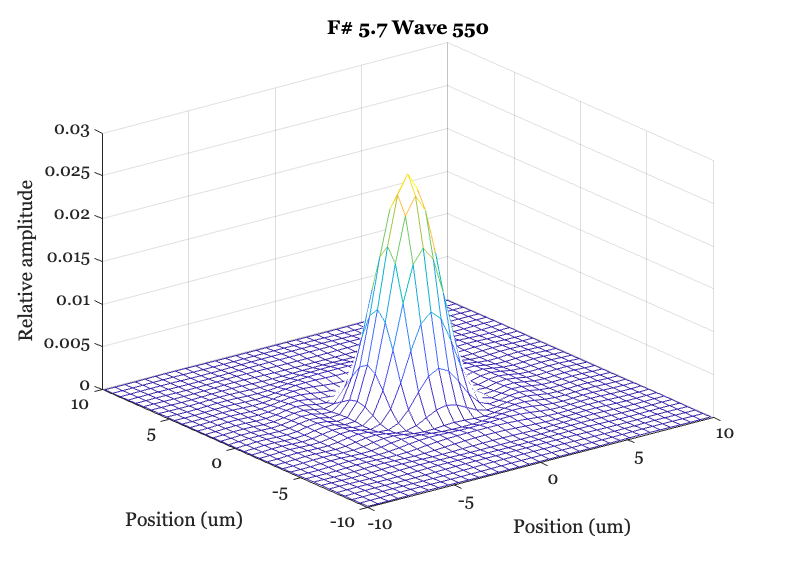

wvf0 = wvfCompute(wvf0);
wList = 550;
wvfPlot(wvf0,'psf','unit','um','wave',wList,'plot range', maxUM/2);

## Examine how the first non-zero Zernike coefficient contributes to the PSF.

The j = 3 coefficient (4th entry in the Zernike vector) is known as oblique astigmatism (with axis at 45 degrees.)  For the low order, wvfSet understands the names.  Type into the Matlab command window 

for a list of available names.  Here is a link to an [astronomy site](https://www.telescope-optics.net/monochromatic_eye_aberrations.htm) with the names. 

oblique_astig = 2;                             
wvf3 = wvfSet(wvf0,'zcoeffs',oblique_astig,{'oblique_astigmatism'});
fprintf('Third Zernike coefficient is %g\n',wvfGet(wvf3,'zcoeffs',3));

Third Zernike coefficient is 2


We use wvfComputePupilFunction separately here. This function is called by wvfCompute, which we will use from now on. We can see that the phase changes seem to be aligned with the + and - 45 degree axes, which makes sense for oblique astigmatism.

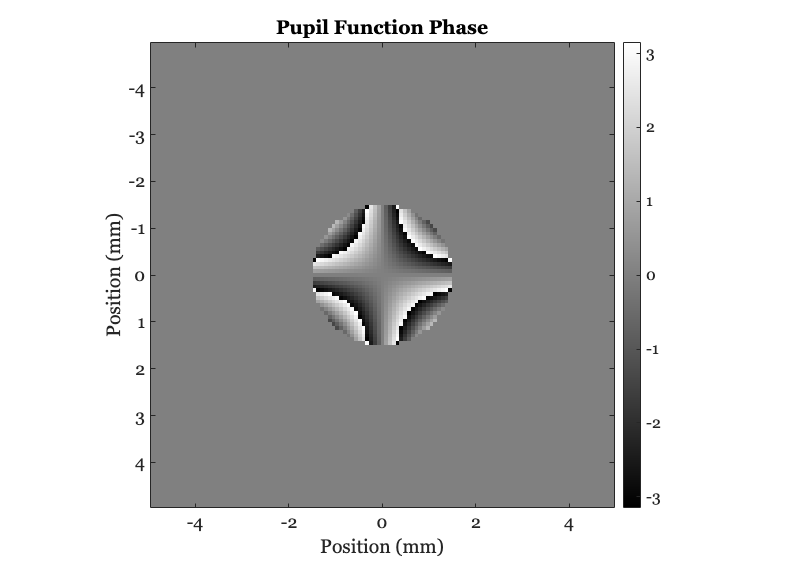

wvf3 = wvfComputePupilFunction(wvf3);
wvfPlot(wvf3,'2d pupil phase space','unit','mm','wave',wList,'plot range',pupilfuncrangeMM);

## Plot the PSF

While the pupil functions are well specified by Zernike polynomials, it's hard to get meaning from them. We'd much prefer to look at the PSF, which gives us an idea of how the pupil will blur an image. This is essentially done by applying a Fourier Transform to the pupil function, which is implemented when we call wvfCompute.

wvf3 = wvfCompute(wvf3); 

We can plot the normalized PSF for a pupil only whose only aberration is the 45 degree astigmatism. As you can see, this no longer looks like the narrow, diffraction-limited PSF. It has also lost its radial symmetry. The higher the order of Zernike polynomial, the more complex the associated PSF will be.

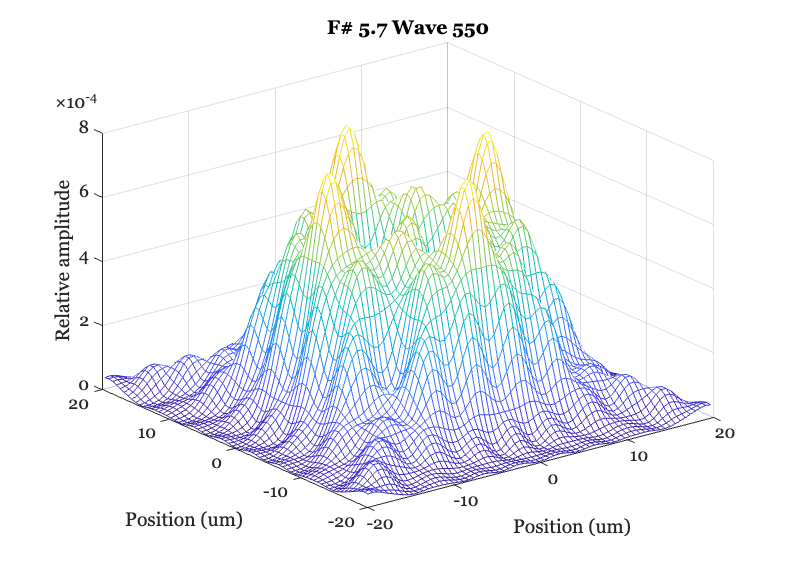

wvfPlot(wvf3, 'psf','unit','um','plot range',maxUM);

## Astigmatism

Astigmatism can be specified along the 0 or 90 degree axis (vertical or horizontal). Unlike the 3rd coefficient, this coefficient for astigmatism is aligned to the x and y axes.

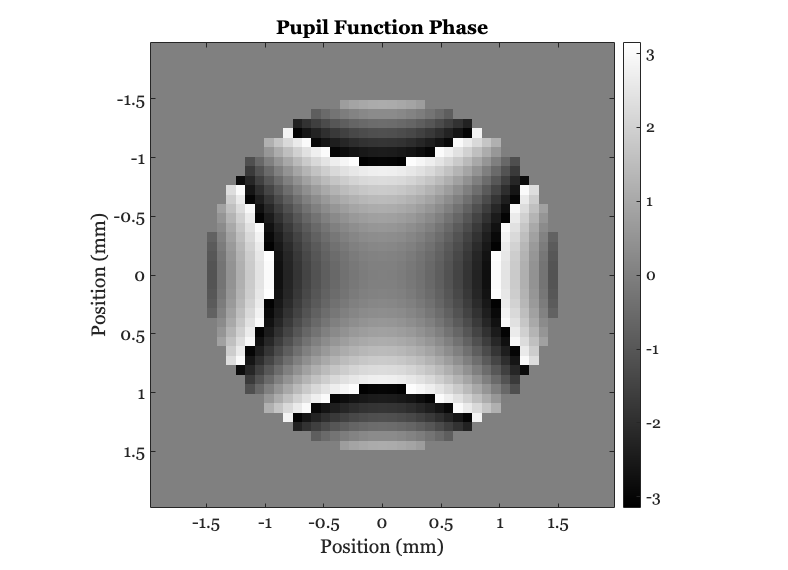

vertical_astig = 2;                         
wvf5 = wvfSet(wvf0,'zcoeffs',vertical_astig,{'vertical_astigmatism'});
wvf5 = wvfCompute(wvf5);
wvfPlot(wvf5,'2d pupil phase space','unit','mm','wave',wList,'plot range',maxMM);

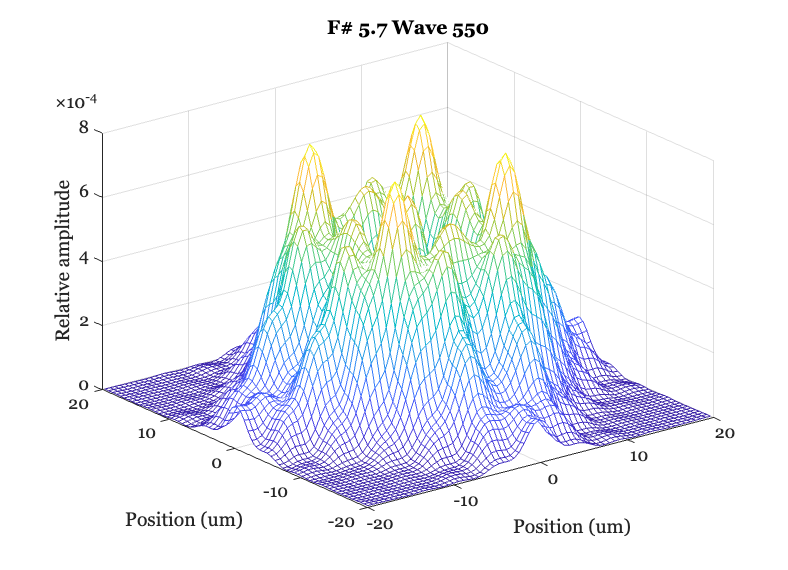

wvfPlot(wvf5,'psf','unit','um','wave',wList,'plot range',maxUM);

## Pupil function PSFs

We loop through the Zernike coefficients to see the effect of changing each. In this loop, we plot the PSF.

The wavefront aberration plots we get match those  [http://www.traceytechnologies.com/resources_wf101.htm](http://www.traceytechnologies.com/resources_wf101.htm) except for the fact that their green is postive and our red is positive. Note that there is considerable disagreement about the Zernikes in the pictures on the web. See comment in v_wvfZernikePolynomials for a more expansive discussion.

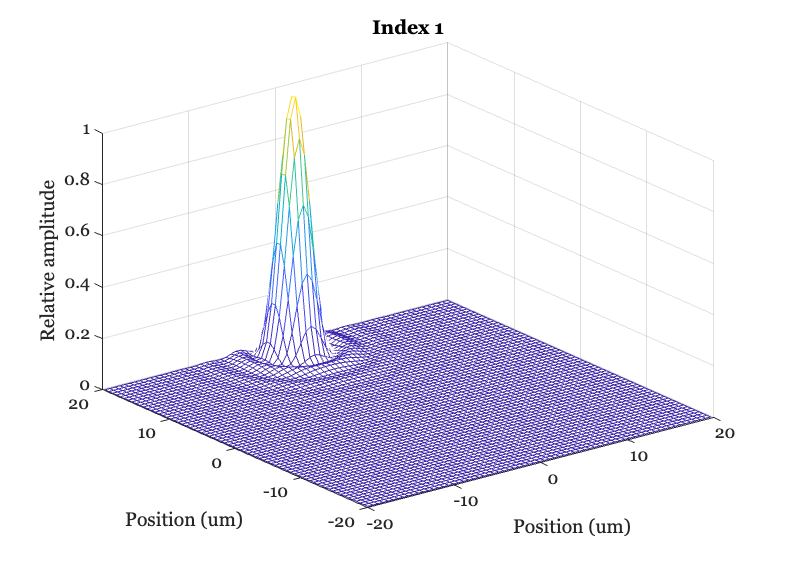

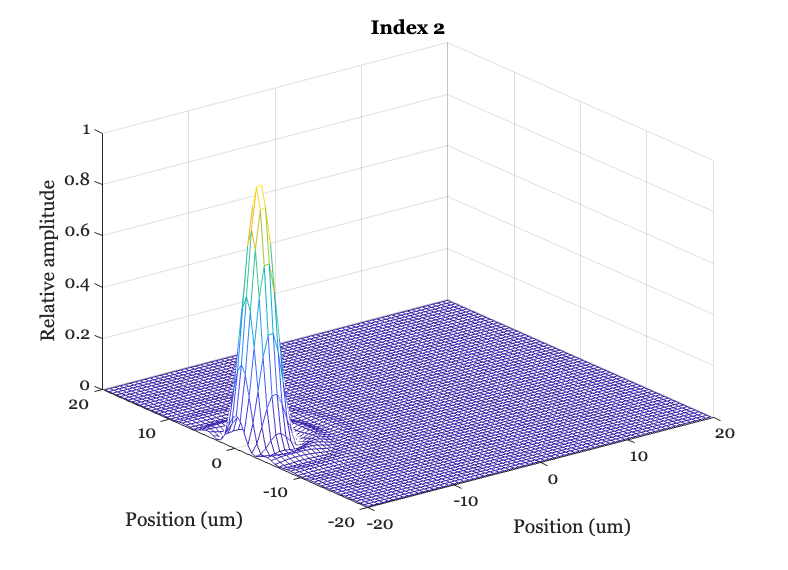

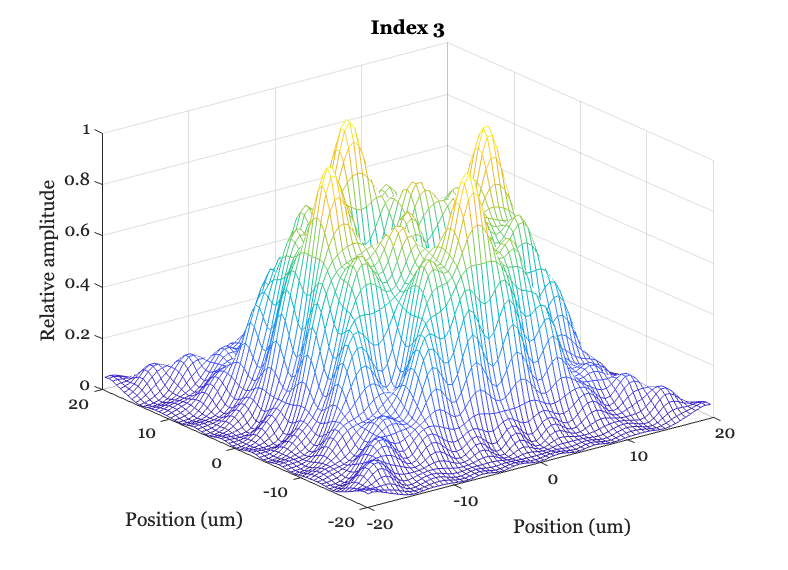

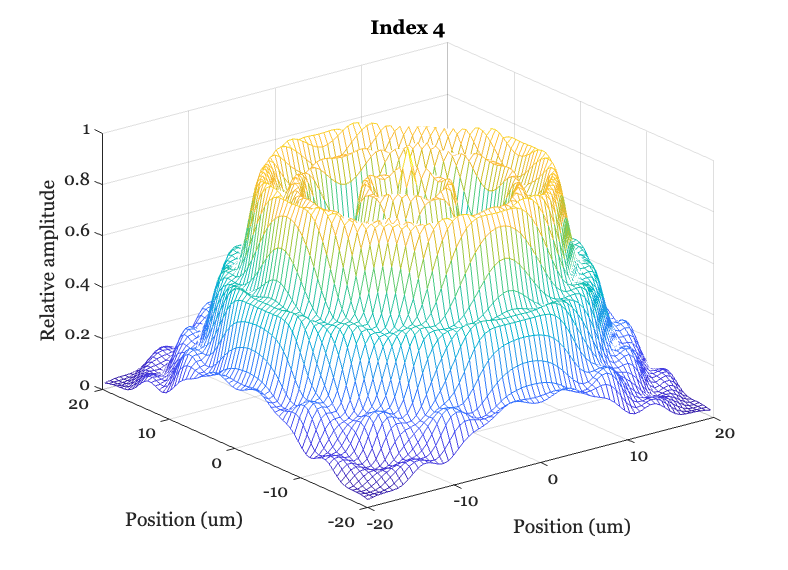

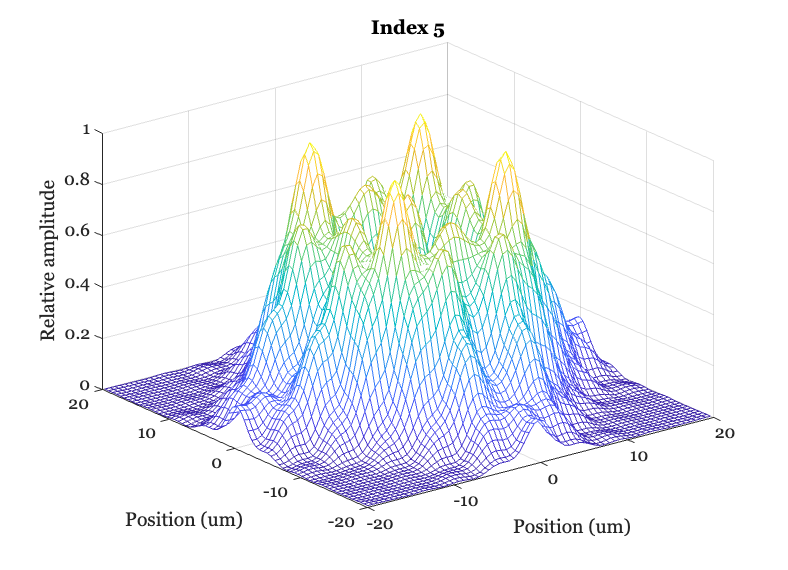

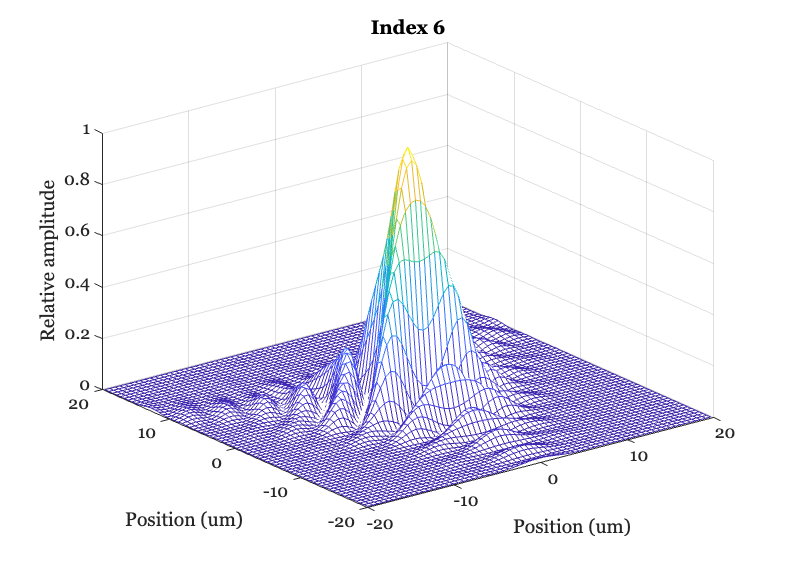

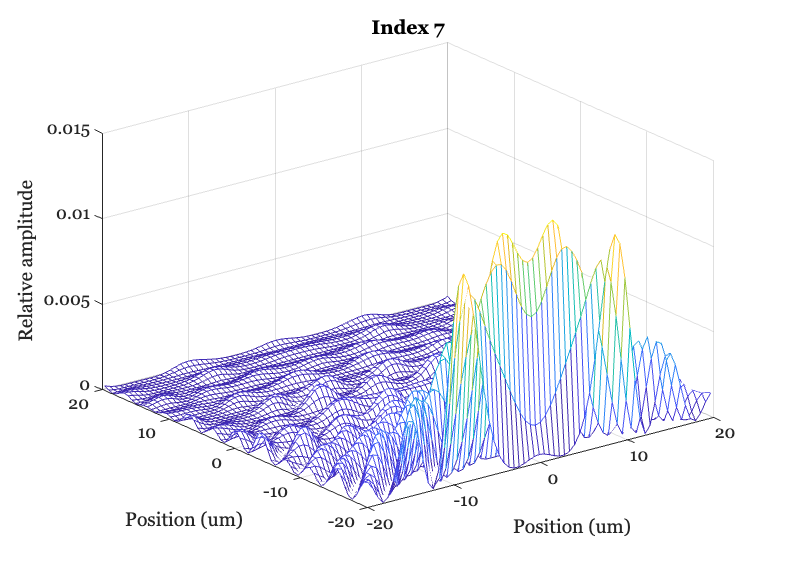

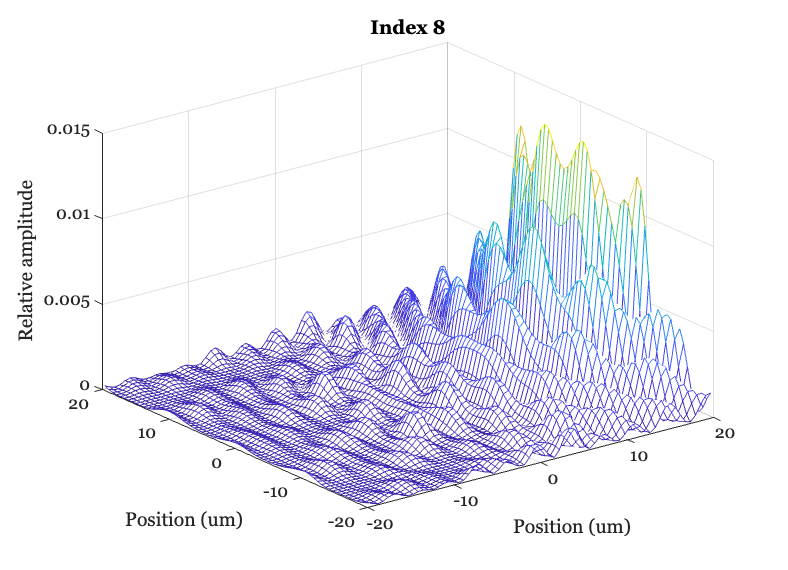

wvf0 = wvfCreate;

% pupilfuncrangeMM = 4;
jindices = 1:9;
maxUM = 20; 
for ii = jindices
    ieNewGraphWin;
    insertCoeff = 2;
    wvf = wvfSet(wvf0,'zcoeffs',insertCoeff,ii);
    wvf = wvfCompute(wvf);
    [n,m] = wvfOSAIndexToZernikeNM(ii);
    wvfPlot(wvf,'psf normalized','unit','um','wave',wList,'plot range',maxUM,'window',false);
    title(sprintf('Index %d',ii))
end

## Longitudinal chromatic aberration (LCA)

Optical systems can have chromatic aberration, where one wavelength is brought into focus but others may be blurry because they are refracted closer or farther from the imaging plane. In this case, the PSF is dependent on wavelength.

The human eye has strong chromatic aberration.  The wavefront code lets us set a variable to incorporate the human LCA as part of the calculation. In the human, this changes mainly Defocus. Aberrations other than "Defocus" are known to vary only slightly with wavelength. 

wvf0 = wvfCreate('wave',400:50:700);
wvf0 = wvfSet(wvf0,'lca method','human');

As a result, the Zernike coefficients don't have to be modified, apart from one. This is the j = 0 "defocus" coefficient. It is what typical eyeglasses correct for using + or - diopters lenses. The wavefront toolbox combines the longitudinal chromatic aberration (LCA) into this coefficient when it calculates the pupil function.  The LCA itself is computed based on the difference between the measurement wavelength (for which the defocus coefficient is specified) and the wavelength being calclated for.

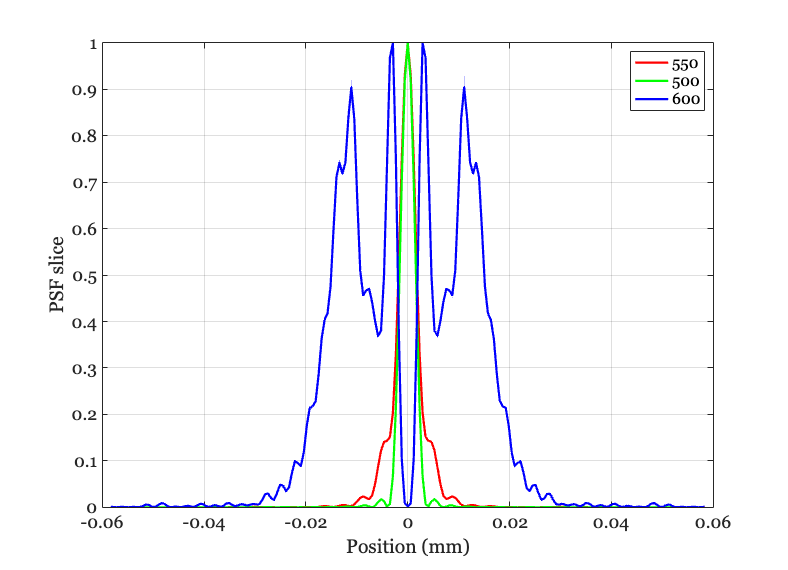

wvf0 = wvfCompute(wvf0);
ieNewGraphWin;
maxMM = 3; 
wvfPlot(wvf0,'1d psf normalized','unit','mm','wave',600,'plot range',maxMM/10,'window',false);
hold on; wvfPlot(wvf0,'1d psf normalized','unit','mm','wave',550,'plot range',maxMM/10,'window',false);
hold on; wvfPlot(wvf0,'1d psf normalized','unit','mm','wave',450,'plot range',maxMM/10,'window',false);
legend({'600','550','450'});

#### Change the calculated wavelength.

The new psf is wider due to the longitudinal chromatic aberration, even though it's still just the diffraction-limited wavefront function (the Zernike coefficients are still 0).

To unpack this, we can do explicitly what is done inside the pupil function calculation.  First we LCA from the wavelength difference, then act as if the measured wavelength (where there is no LCA) is the calculated wavelength.  We do this by changing the measured wavelength specification.  Finally, we add in the LCA to the defocus coefficient.

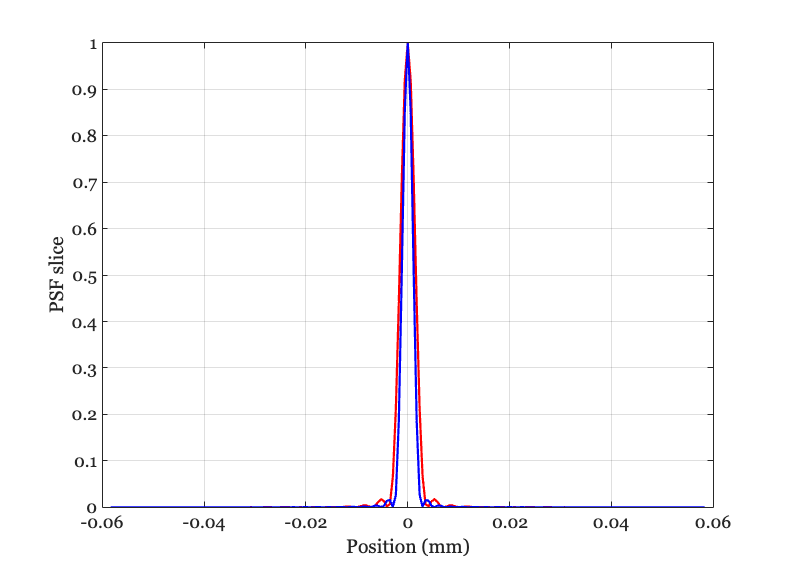

wvf2 = wvf1;
lcaDiopters = wvfLCAFromWavelengthDifference(wvfGet(wvf2,'wavelength','nm'),wvfGet(wvf2,'wavelengths','nm'));
lcaMicrons = wvfDefocusDioptersToMicrons(-lcaDiopters,wvfGet(wvf2,'pupil size'));
wvf2 = wvfSet(wvf2,' wavelength',wvfGet(wvf2,' wavelengths','nm'));
wList = wvfGet(wvf2,' wavelengths');
defocus = wvfGet(wvf2,'zcoeffs',{'defocus'});
defocus = defocus + lcaMicrons;
wvf2 = wvfSet(wvf2,'zcoeffs',lcaMicrons,{'defocus'});
wvf2 = wvfCompute(wvf2);
[udataS, pData] = wvfPlot(wvf2,'1dpsf normalized','unit','mm','wave',wList,'plot range',maxMM,'window',false);

set(pData,'color','b','linewidth',2);